% Question 1

Y = [1, 10, 12, 5, 8, 10];
X = [0, 1, 2, 3, 4, 5];
sx = X;
sy = Y;

plot_x = 0:0.1:5;
plot_y = zeros(1,length(plot_x));
for i=1:length(plot_x)
    plot_y(i) = interpolate(X, Y, plot_x(i));
end

coefficients(X,Y)

ans =    -0.4250    5.1250  -20.4583   28.3750   -3.6167    1.0000


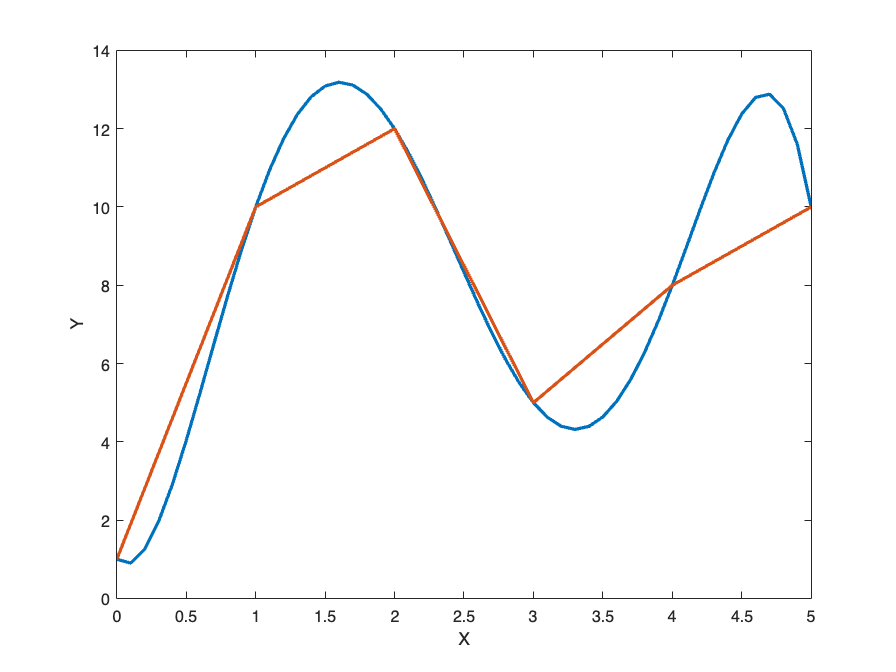

plot(plot_x,plot_y,LineWidth=2);
hold on 
plot(sx,sy,LineWidth=2);
hold off;

xlabel('X');
ylabel('Y');

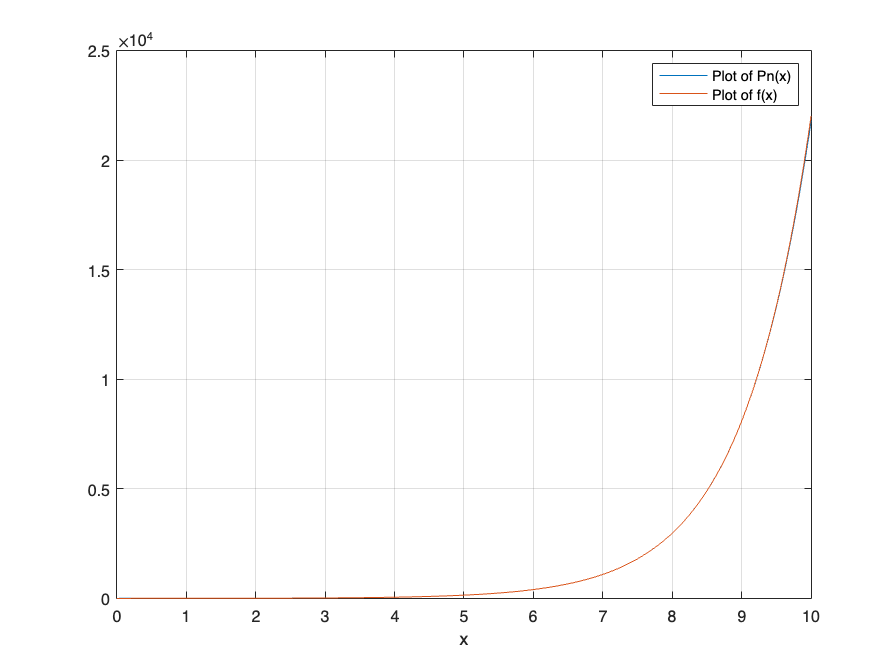

% Question 2

n = 10;
xn = 0:1:10;
yn = exp(xn);
x = 0:0.001:10;
fx = exp(x);
Pn = f(x, n, yn, xn);
plot(x, [Pn;fx]);
legend('Plot of Pn(x)','Plot of f(x)');
xlabel('x');
grid on;


plot(X_inter,Y_inter,'--',LineWidth=2);
coeff = lp(n,xn,yn)

coeff =     0.0001   -0.0024    0.0427   -0.4318    2.7382  -11.1438   28.9944  -45.5089   39.6787  -12.6490    1.0000


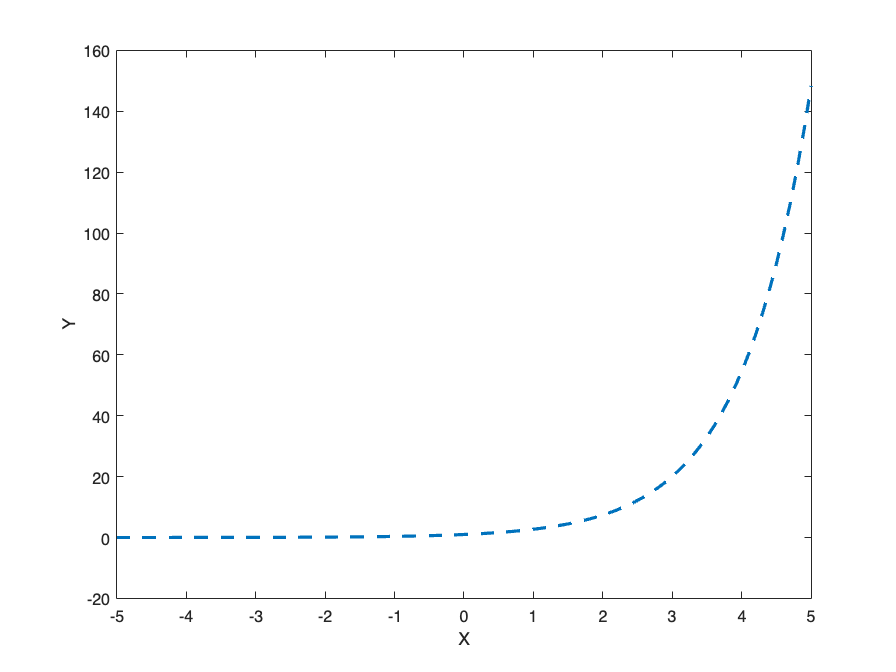


xlabel('X');
ylabel('Y');

function ret = interpolate(X,Y,x)
% X is a vector of x values
% Y is a vector of y values
% x is the value to interpolate
% ret is the interpolated value
    y = 0;
    for i = 1:length(X)
        temp = 1;
        for j = 1:length(X)
            if i ~= j
                temp = temp * (x - X(j))/(X(i) - X(j));
            end
        end
        y = y + temp * Y(i);
    end
    ret = y;
end


function sum = coefficients(X,Y)
sum =0;
for i=1:length(X)
    p=1;
    for j=1:length(X)
        if j~=i
            c = poly(X(j))/(X(i)-X(j));
            p = conv(p,c);
        end
    end
    term = p*Y(i);
    sum= sum + term;
end
    
end


function Lp = lp(n , x_n, y_n)

sum=0;
for i=1:length(x_n)
    p=1;
    for j=1:length(x_n)
        if j~=i
            c = poly(x_n(j))/(x_n(i)-x_n(j));
            p = conv(p,c);
        end
    end
    term = p*y_n(i);
    sum= sum + term;
end
 Lp = sum;
end


function y = f(x, n, f_n, x_n)
    y = 0;
    for i = 1:n
        y = y + L_n(x, i, x_n, n) .* f_n(i);
    end
end

function y = L_n(x, nth, x_n, n)
    y = 1;
    for i = 1:n
        if i ~= nth
            y = y.*(x - x_n(i))/(x_n(nth) - x_n(i));
        end
    end
end